# Caso de Estudo - Secagem de Grãos

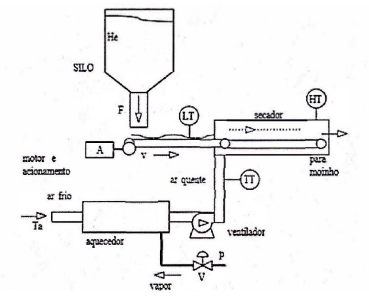

Definido s como transformada de laplace:

s = tf('s');

#### Dados e Modelos:

G1 = 1/(1.6*s + 1);
G2 = 1/(40*s + 1);
G3 = 0.8/(50*s + 1);

G4 = 7/(0.7*s + 1);
G5 = 0.5/(0.5*s + 1);
G6 = 3/(0.5*s + 1);
G7 = 5/(3*s + 1);

#### Diagrama de malha aberta:

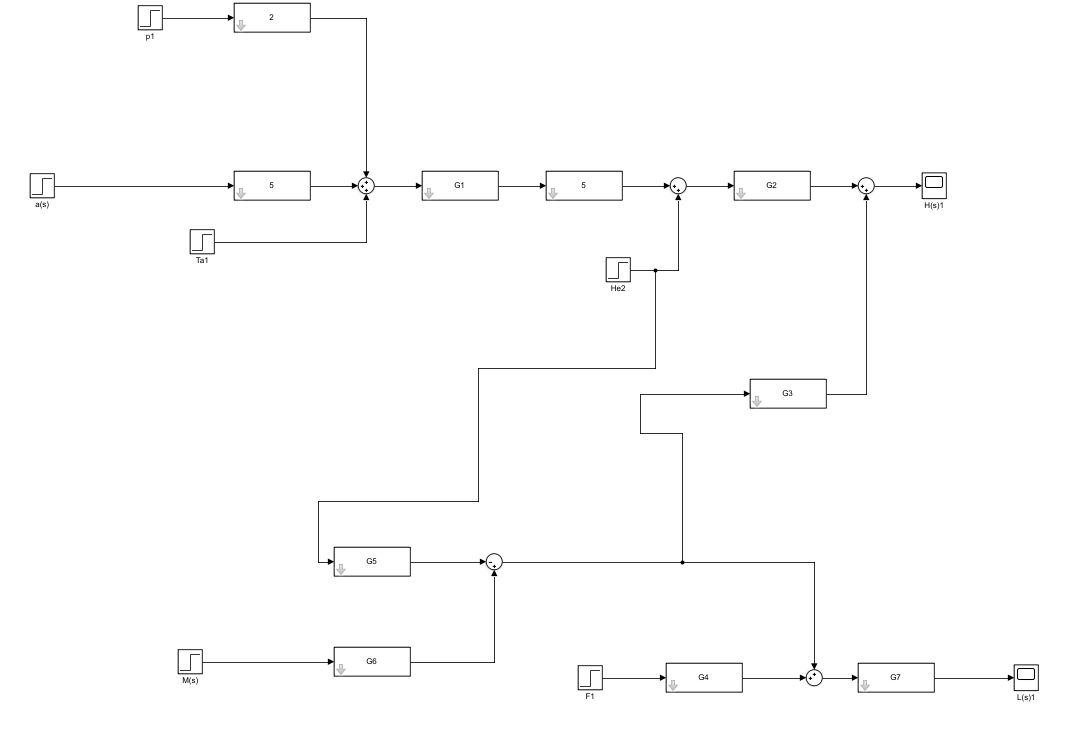

#### Proposta de controle:

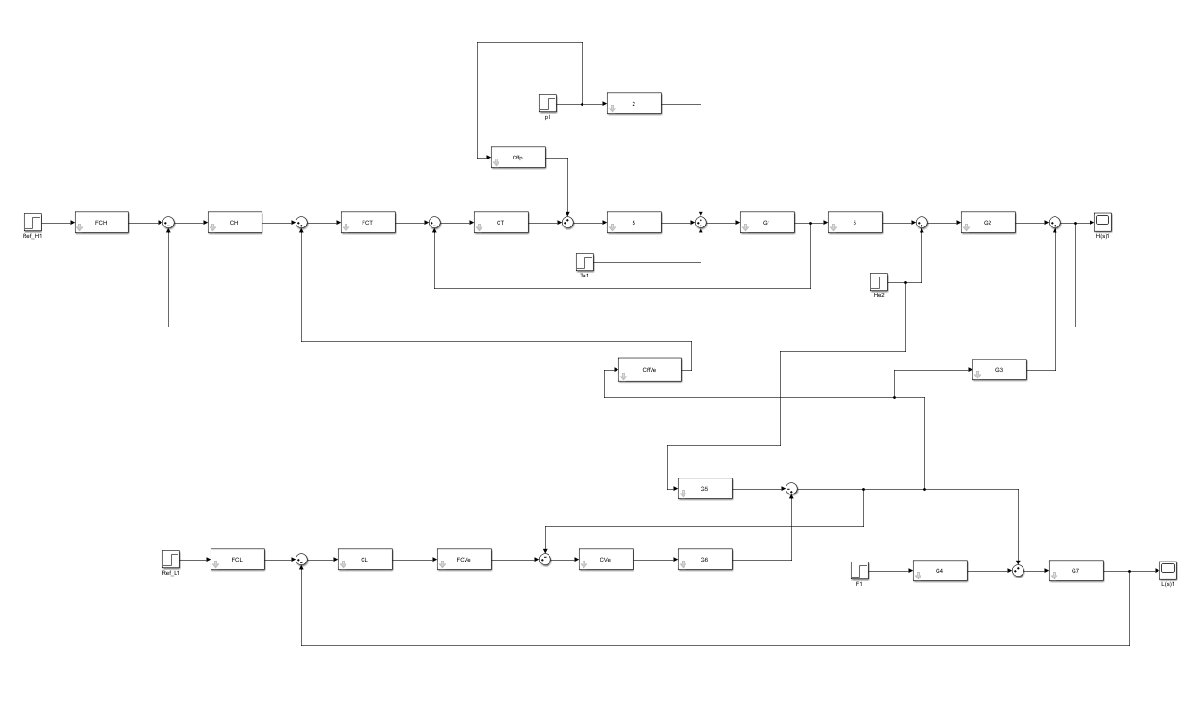

### Dados e Modelos manipulado:

Abertura da válvula de vapor para emperatura do ar quente na entrada do secador

GaT = 5/(1.6*s + 1);

Temperatura do ar quente na entrada do secador para umidade do grão na saída do secador

GTH = 5/(40*s + 1);

Acionamento do motor elétrico da esteira para velocidade da esteira

GMVe = 3/(0.5*s + 1);

Velocidade da esteira para camada de grãos na esteira

GVeL = 5/(3*s + 1);

 Pertubação - Pressão na linha de vapor para Temperatura do ar quente na entrada do secador

GpT = 2/(1.6*s + 1);

 Perturbação - Temperatura do ar na entrada do aquecedor para Temperatura do ar quente na entrada do secador

GTaT = 1/(1.6*s + 1);

Perturbação - Umidade do grão no slio para umidade do grão na saída do secador

GHeH = 1/(40*s + 1);

 Perturbação - Velocidade da esteira para umidade do grão na saída do secador

GVeH = 0.8/(50*s + 1);

 Perturbação - Vazão de grão do silo na esteira para camada de grãos na esteira

GFL = 35/((3*s + 1)*(0.7*s + 1));

 Perturbação - Umidade de grão no silo para camada de grãos na esteira

GHeVe = 0.5/(0.5*s + 1);

###  Requisitor para controle da umidade H(s):

 Erro nulo para mudanças de referência do tipo degrau

 Erro nulo para perturbações do tipo degrau

 t5% de malha fechada duas vezes mais rápida que malha aberta para 

 Respostas de seguimento e rejeição de perturbação. Fazendo essa conta

 t5% <= 60seg

 MP = 5%

###  Objetivo da Etrutura de Controle de H(s):

 Foi utilizado uma estrutura de controle em cascata para o sistema, pois o processo possui um medidor para a Temperatura do ar quente na entrada do secador (T) disponível, e as perturbações, temperatura do ar na entrada do aquecedor (Ta) e pressão na linha de vapor (p), influênciam diretamente na temperatura do ar quente na entrada do secador. Desta forma a estrutura de controle em cascata é uma alternativa viavél e indicada para  melhorar a rejeição das perturbações, além de facilitar o projeto dos  controladores da estrutura.

### Objetivo de cada controlador:

 CT: Seguir as referências dadas pelo controlador CH, com erro nulo em regime permanete com tempo de acomodação para rejeição e perturbação pelo  menos 10x mais rápida que a malha de controle CH. Para auxiliar CT foi  adicionado um CFF na perturbação (p), pois esta perturbação é mensurável.

#### Requsitos para CT:

 Sobressinal 5%

 t5% = 6 seg para referência e perturbação

 rejeitar perturbação

 CH: Seguir as referências de H com erro nulo em regime permanete com tempo de acomodação inferior a 60seg, rejeitar as perturbações com erro nulo em regime permanente com tempo de acomodação inferior a 60 seg. Para auxiliar CH foi adicionado um CFF na perturbação (Ve), pois esta  perturbação é mensurável.

#### Requsitos para CH:

 Sobressinal 5%

 t5% = 60 seg para referência e perturbação

 rejeitar perturbação

##  Projeto de CT:

MP = 0.05, t5 = 6

Kc = 0.12;
Ti = (5*0.12)/(1.6*(0.7245^(2)));

#### Controlador:

CT = (Kc*(Ti*s+1))/(Ti*s)

CT =
 
  0.08573 s + 0.12
  ----------------
      0.7144 s
 
Continuous-time transfer function.



Tr = (CT*GaT)/(1+CT*GaT);
Tr = (minreal(Tr,0.0001))

Tr =
 
  0.375 s + 0.5249
  ----------------
  s^2 + s + 0.5249
 
Continuous-time transfer function.



#### Análise do Controlador CT

 Resposta ao degrau de Tr

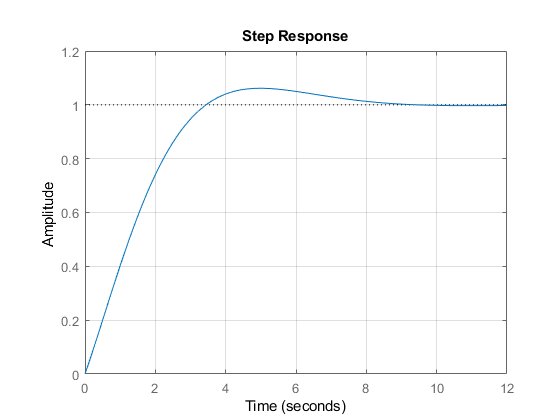

figure;
step(Tr) 
grid on

Diagrama Polo e Zero - DPZ

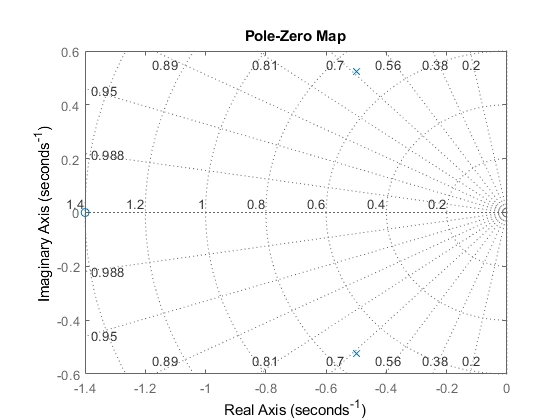

figure;
pzmap(Tr) 
grid on

 Como podemos observar aparece um zero indesejado, projetamos um filtro para retirar esse zero:

FCT = 1/(Ti*s+1);
TrfT = FCT*Tr;
TrfT = minreal(TrfT,0.00001)

TrfT =
 
       0.5249
  ----------------
  s^2 + s + 0.5249
 
Continuous-time transfer function.



Resposta ao degrau de Trf

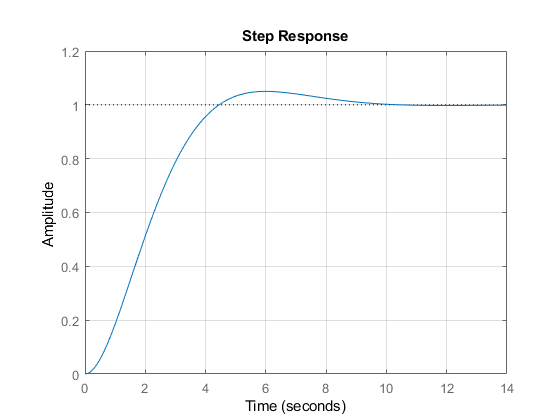

figure;
step(TrfT) 
grid on

 Diagrama Polo e Zero - DPZ

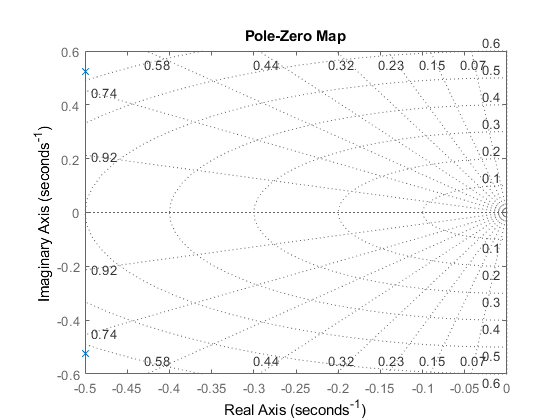

figure;
pzmap(TrfT) 
grid on

 Tempo de 5% para Referência:

info = stepinfo(TrfT,'SettlingTimeThreshold',0.05)

info = struct with fields:
        RiseTime: 2.8947
    SettlingTime: 3.9468
     SettlingMin: 0.9004
     SettlingMax: 1.0500
       Overshoot: 4.9990
      Undershoot: 0
            Peak: 1.0500
        PeakTime: 5.9867


T5MF = info.SettlingTime

T5MF = 3.9468

Sobressinal da referência:

MP = info.Overshoot

MP = 4.9990

 Ganho DC = 1:

GDC = dcgain(Tr)

GDC = 1.0000

 Verificando agora para Perturbarção, Calculando Tp(s):

Tp = GTaT/(1+CT*GaT);
Tp = zpk(minreal(Tp,0.0001))

Tp =
 
       0.625 s
  ------------------
  (s^2 + s + 0.5249)
 
Continuous-time zero/pole/gain model.



A resposta a entrada ao degrau em Ta, apresenta a rejeição conforme esperado.

Resposta ao degrau de Tp

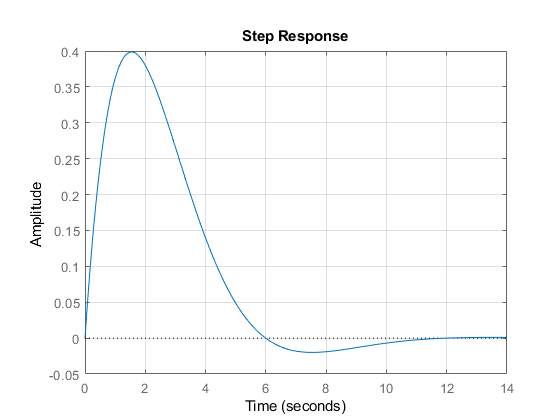

figure; 
step(Tp) 
grid on

Diagrama polo zero DPZ

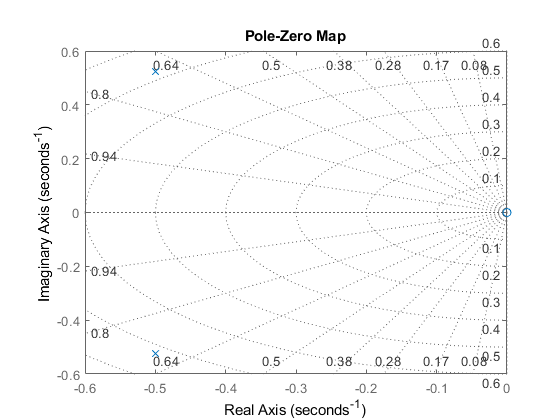

figure;
pzmap(Tp) 
grid on

 Como esperado o Ganho DC é igual a zero logo atende as especificações desejadas.

GDC = dcgain(Tp);

 Controlador FF para a perturbação p(s):

Cffp = -2/5;

##  Projeto de CH:

MP = 0.05, t5 = 60

Kc = 0.6;
Ti = (0.6)/(8*(0.072^(2)));

#### Controlador:

CH = (Kc*(Ti*s+1))/(Ti*s)

CH =
 
  8.681 s + 0.6
  -------------
     14.47 s
 
Continuous-time transfer function.



Tr = (CH*GTH)/(1+CH*GTH);
Tr = (minreal(Tr,0.0001))

Tr =
 
    0.075 s + 0.005184
  ----------------------
  s^2 + 0.1 s + 0.005184
 
Continuous-time transfer function.



####  Análise do Controlador CH

Resposta ao degrau de Tr

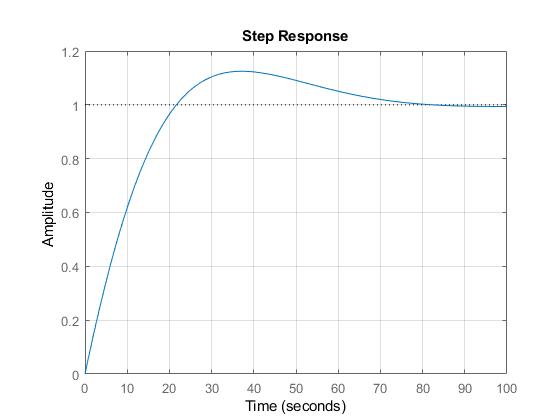

figure;
step(Tr) 
grid on

 Diagrama Polo e Zero - DPZ

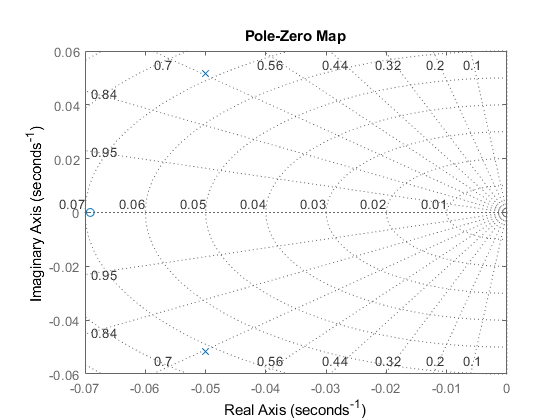

figure;
pzmap(Tr) 
grid on

 Como podemos observar aparece um zero indesejado, projetamos um filtro para retirar esse zero:

FCH = 1/(Ti*s+1);
TrfH = FCH*Tr;
TrfH = minreal(TrfH,0.00001)

TrfH =
 
         0.005184
  ----------------------
  s^2 + 0.1 s + 0.005184
 
Continuous-time transfer function.



Resposta ao degrau de Trf

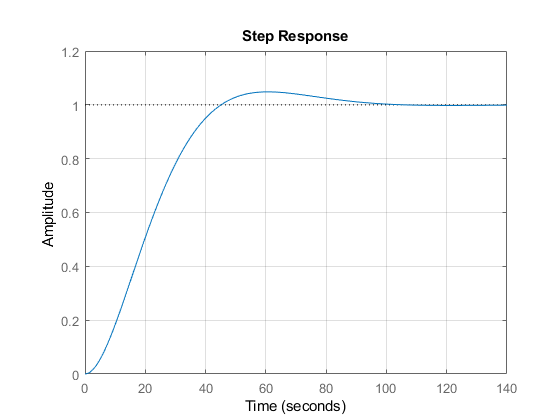

figure;
step(TrfH)
grid on

Diagrama Polo e Zero - DPZ

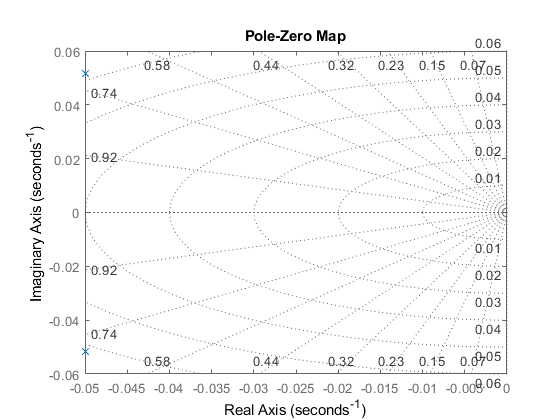

figure;
pzmap(TrfH) 
grid on

 Tempo de 5% para Referência:

info = stepinfo(TrfH,'SettlingTimeThreshold',0.05)

info = struct with fields:
        RiseTime: 29.3127
    SettlingTime: 39.9633
     SettlingMin: 0.9082
     SettlingMax: 1.0482
       Overshoot: 4.8217
      Undershoot: 0
            Peak: 1.0482
        PeakTime: 60.7882


T5MF = info.SettlingTime

T5MF = 39.9633

Sobressinal da referência:

MP = info.Overshoot

MP = 4.8217

Ganho DC = 1:

GDC = dcgain(Tr);

 Verificando agora para Perturbarção, Calculando He(s):

Tp = GHeH/(1+CH*GTH);
Tp = zpk(minreal(Tp,0.0001))

Tp =
 
          0.025 s
  -----------------------
  (s^2 + 0.1s + 0.005184)
 
Continuous-time zero/pole/gain model.



 A resposta a entrada ao degrau em He, apresenta a rejeição conforme esperado.

 Resposta ao degrau de Tp

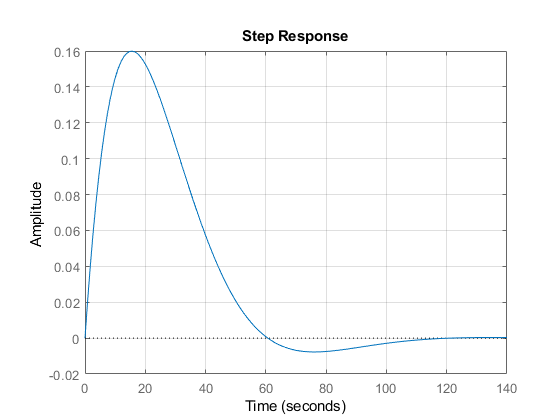

figure; 
step(Tp)
grid on

 Diagrama polo zero DPZ

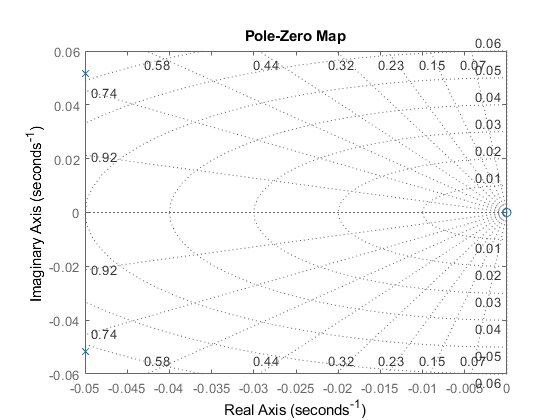

figure;
pzmap(Tp)
grid on

Como esperado o Ganho DC é igual a zero logo atende as especificações desejadas.

GDC = dcgain(Tp);

 Controlador FF para a perturbação Ve(s):

CffVe = (-32*s - 0.8)/(250*s + 5);

##  Requisitor para controle da camada de grãos L(s):

 Erro nulo para mudanças de referência do tipo degrau

 Erro nulo para perturbações do tipo degrau

 t5% <= 5 para tespostas de seguimento e rejeição de perturbação.

 MP = 0

####  Objetivo da Etrutura de Controle de L(s):

 Foi utilizado uma estrutura de controle em cascata para o sistema, pois o processo possui um medidor para a velocidade da esteira (Ve), e a  perturbação, umidade do grão no silo (He),influência diretamente na velocidade da esteira. Desta forma a estrutura de controle em cascata  é uma alternativa viavél e indicada para melhorar a rejeição das perturbações, além de facilitar o projeto dos controladores da estrutura.

####  Objetivo de cada controlador:

 CVe: Seguir as referências dadas pelo controlador CL, com erro nulo em  regime permanete com tempo de acomodação para rejeição e perturbação pelo  menos 10x mais rápida que a malha de controle CL.

Requsitos para CVe:

 Sobressinal = 0

 t5% <= 0,5 seg para referência e perturbação

 rejeitar perturbação

 CL: Seguir as referências de L com erro nulo em regime permanete com

 tempo de acomodação inferior a 5 seg, rejeitar as perturbações com erro

 nulo em regime permanente com tempo de acomodação inferior a 5 seg.

Requsitos para CL:

 Sobressinal = 0

 t5% <= 5 seg para referência e perturbação

 rejeitar perturbação

##  Projeto de CVe:

MP = 0, t5 = 0,5

Kc = 8.6/3;
Ti = 8.6/46.08;

Controlador:

CVe = (Kc*(Ti*s+1))/(Ti*s)

CVe =
 
  0.535 s + 2.867
  ---------------
     0.1866 s
 
Continuous-time transfer function.



Tr = (CVe*GMVe)/(1+CVe*GMVe);
Tr = (minreal(Tr,0.0001))

Tr =
 
     17.2 s + 92.16
  --------------------
  s^2 + 19.2 s + 92.16
 
Continuous-time transfer function.



#### Análise do Controlador CVe

Resposta ao degrau de Tr

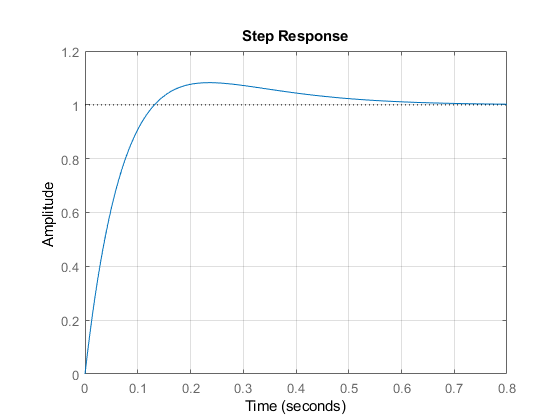

figure;
step(Tr) 
grid on

Diagrama Polo e Zero - DPZ

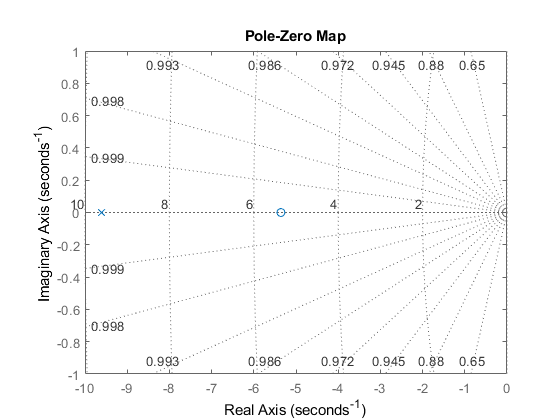

figure;
pzmap(Tr) 
grid on

 Como podemos observar aparece um zero indesejado, projetamos um filtro para retirar esse zero:

FCVe = 1/(Ti*s+1);
TrfVe = FCVe*Tr;
TrfVe = minreal(TrfVe,0.00001)

TrfVe =
 
         92.16
  --------------------
  s^2 + 19.2 s + 92.16
 
Continuous-time transfer function.



 Resposta ao degrau de Trf

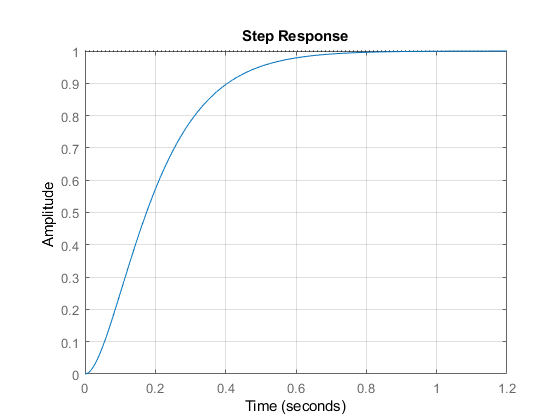

figure;
step(TrfVe) 
grid on

Diagrama Polo e Zero - DPZ

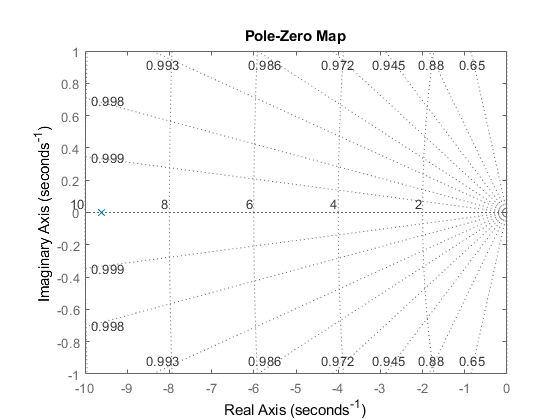

figure;
pzmap(TrfVe) 
grid on

Tempo de 5% para Referência:

info = stepinfo(TrfVe,'SettlingTimeThreshold',0.05)

info = struct with fields:
        RiseTime: 0.3498
    SettlingTime: 0.4942
     SettlingMin: 0.9019
     SettlingMax: 0.9999
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9999
        PeakTime: 1.2424


T5MF = info.SettlingTime

T5MF = 0.4942

 Sobressinal da referência:

MP = info.Overshoot

MP = 0

 Ganho DC = 1:

GDC = dcgain(Tr);

 Verificando agora para Perturbarção, Calculando Tp(s):

Tp = GHeVe/(1+CVe*GMVe);
Tp = zpk(minreal(Tp,0.0001))

Tp =
 
      s
  ---------
  (s+9.6)^2
 
Continuous-time zero/pole/gain model.



 A resposta a entrada ao degrau em Ta, apresenta a rejeição conforme esperado.

Resposta ao degrau de Tp

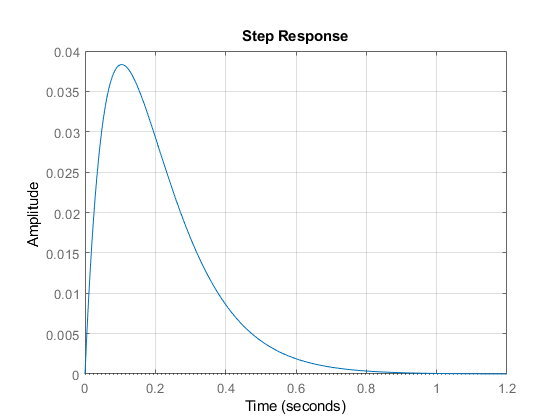

figure; 
step(Tp) 
grid on

Diagrama polo zero DPZ

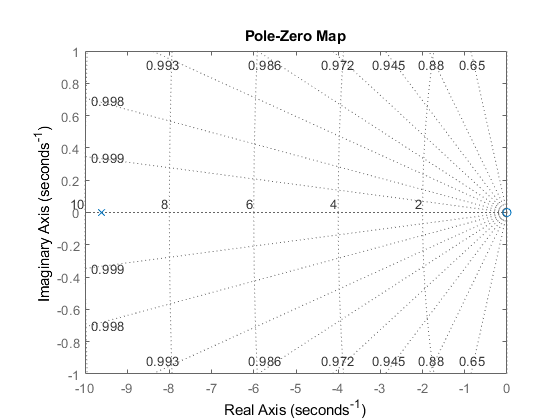

figure;
pzmap(Tp) 
grid on

 Como esperado o Ganho DC é igual a zero logo atende as especificações desejadas.

GDC = dcgain(Tp);

####  Projeto de CL:

MP = 0, t5 = 5

Kc = 0.952;
Ti = (5*0.952)/(3*0.9216);

Controlador:

CL = (Kc*(Ti*s+1))/(Ti*s)

CL =
 
  1.639 s + 0.952
  ---------------
      1.722 s
 
Continuous-time transfer function.



Tr = (CL*GVeL)/(1+CL*GVeL);
Tr = (minreal(Tr,0.0001))

Tr =
 
    1.587 s + 0.9216
  ---------------------
  s^2 + 1.92 s + 0.9216
 
Continuous-time transfer function.



####  Análise do Controlador CL

Resposta ao degrau de Tr

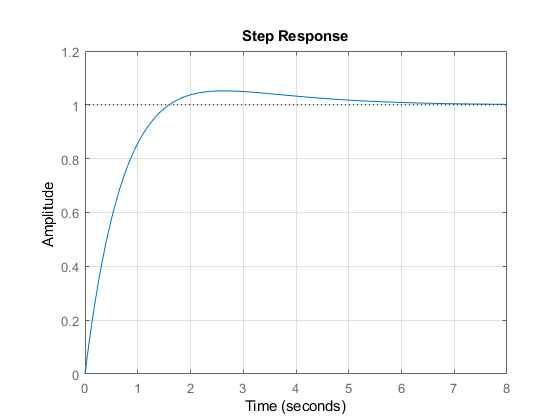

figure;
step(Tr) 
grid on

Diagrama Polo e Zero - DPZ

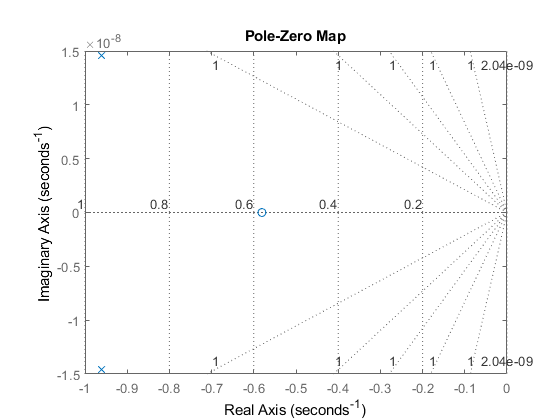

figure;
pzmap(Tr)
grid on

 Como podemos observar aparece um zero indesejado, projetamos um filtro para retirar esse zero:

FCL = 1/(Ti*s+1);
TrfL = FCL*Tr;
TrfL = minreal(TrfL,0.00001);

Resposta ao degrau de Trf

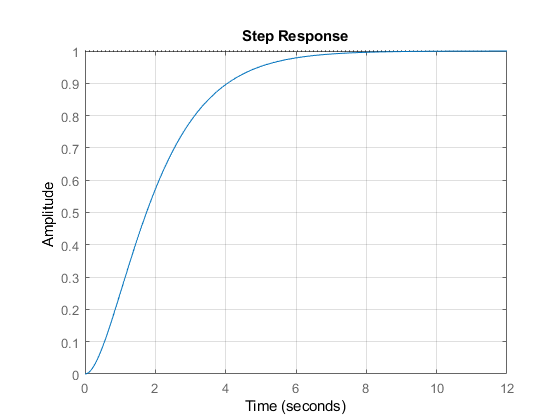

figure;
step(TrfL) 
grid on

Diagrama Polo e Zero - DPZ

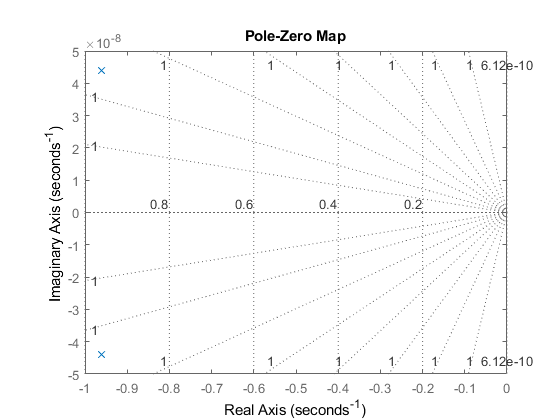

figure;
pzmap(TrfL) 
grid on

 Tempo de 5% para Referência:

info = stepinfo(TrfL,'SettlingTimeThreshold',0.05)

info = struct with fields:
        RiseTime: 3.4983
    SettlingTime: 4.9415
     SettlingMin: 0.9019
     SettlingMax: 0.9999
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9999
        PeakTime: 12.4244


T5MF = info.SettlingTime

T5MF = 4.9415

 Sobressinal da referência:

MP = info.Overshoot

MP = 0

 Ganho DC = 1:

GDC = dcgain(Tr);

####  Verificando agora para Perturbarção, Calculando Tp(s):

Tp = GFL/(1+CL*GVeL)

Tp =
 
                 180.8 s^2 + 60.26 s
  --------------------------------------------------
  10.85 s^4 + 39.94 s^3 + 51.85 s^2 + 27.53 s + 4.76
 
Continuous-time transfer function.



Tp = zpk(minreal(Tp,0.0001))

Tp =
 
        16.667 s
  --------------------
  (s+1.429) (s+0.96)^2
 
Continuous-time zero/pole/gain model.



 A resposta a entrada ao degrau em Ta, apresenta a rejeição conforme esperado.

Resposta ao degrau de Tp

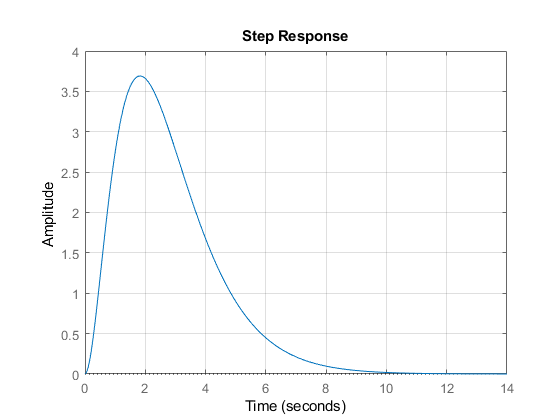

figure; 
step(Tp)  
grid on

Diagrama polo zero DPZ

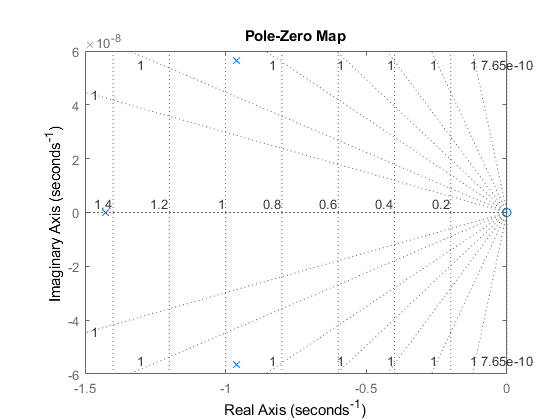

figure;
pzmap(Tp)  
grid on

 Tempo de 5% para Referência:

info = stepinfo(Tp,'SettlingTimeThreshold',0.05)

info = struct with fields:
        RiseTime: 0
    SettlingTime: 7.1823
     SettlingMin: 8.3403e-05
     SettlingMax: 3.6909
       Overshoot: Inf
      Undershoot: 0
            Peak: 3.6909
        PeakTime: 1.8229


T5MF = info.SettlingTime

T5MF = 7.1823

Sobressinal da referência:

MP = info.Overshoot

MP = Inf

 Como esperado o Ganho DC é igual a zero logo atende as especificações desejadas.

GDC = dcgain(Tp)

GDC = 0

##  Simulação do Sitemas Completo:

Executa o arquivo do simulink

out = sim('secagem_de_graos_simulink.slx');  

###  Cenário simulado:

 Mudança de reférência do tipo degrau em 50seg para H(s)

 Mudança de reférência do tipo degrau em 10seg para L(s)

 10seg Perturbação em p com amplitude 1

 7seg Perturbação em Ta com amplitude 1

 20seg Perturbação em He com amplitude 1

 20seg Perturbação em F com amplitude 1

####  Erros dos controladores CH e CT

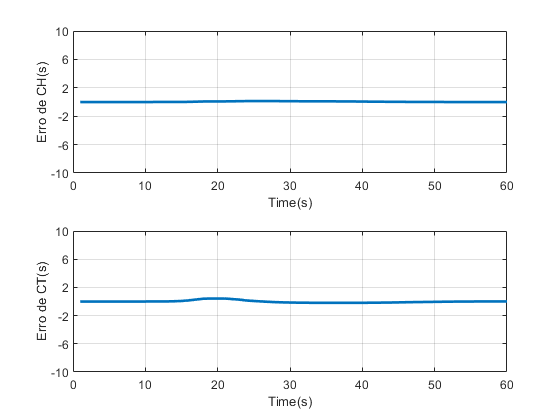

figure;
subplot(2,1,1)
plot(out.erro1.signals.values(:,1), 'LineWidth', 2)
xlabel("Time(s)")
ylabel("Erro de CH(s)")
grid on
xlim([0 60])
ylim([-10 10])
yticks([-10:4:60])

subplot(2,1,2)
plot(out.erro1.signals.values(:,2),'LineWidth',2)
xlabel("Time(s)")
ylabel("Erro de CT(s)")
grid on
xlim([0 60])
ylim([-10 10])
yticks([-10:4:60])

 Sinal do erro dos controladores CH(s), e CT(s), observa-se que os dois controladores conseguem sempre levar o erro para zero após cada perturbação ou mudanção de referência garantindo assim o erro nulo em regime permanente

####  Erros dos controladores CL e CVe

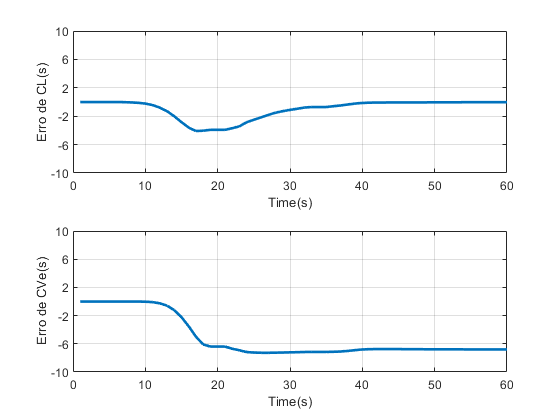

figure;
subplot(2,1,1)
plot(out.erro2.signals.values(:,1), 'LineWidth', 2)
xlabel("Time(s)")
ylabel("Erro de CL(s)")
grid on
xlim([0 60])
ylim([-10 10])
yticks([-10:4:60])

subplot(2,1,2)
plot(out.erro2.signals.values(:,2),'LineWidth',2)
xlabel("Time(s)")
ylabel("Erro de CVe(s)")
grid on
xlim([0 60])
ylim([-10 10])
yticks([-10:4:60])

 Sinal do erro do controlador CL(s),  observa-se que ele conseguem  sempre levar o erro para zero após cada perturbação ou mudanção de  referência mas o controlador Cve(s)leva o erro para proximo de -7, após a perturbação F(s) atuar

###  Controle de H(s):

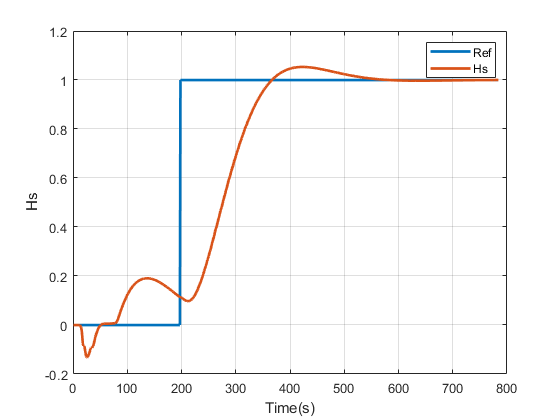

figure;
plot(out.Hs.signals.values(:,1),'LineWidth',2)
hold on
plot(out.Hs.signals.values(:,2),'LineWidth',2)
xlabel("Time(s)")
ylabel("Hs")
legend('Ref','Hs')
grid on

 Observa-se que o controlador CH consegue seguir as referências dadas com o sobressinal dentro do requisito, no instante 10 quando a perturbação p atua no sistema observa-se que a diversas ociçaões. E que também o cff ajuda a ignorar a perturbação de Ve;

###  Controle de T(s):

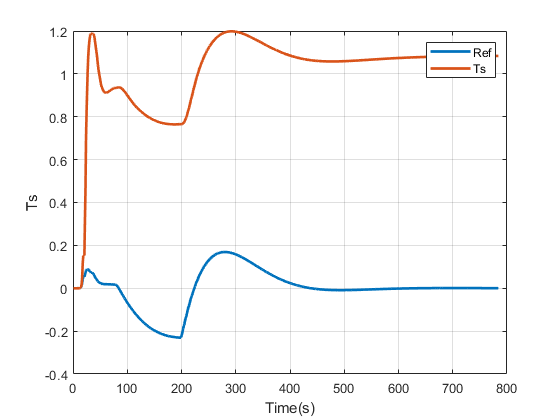

figure;
plot(out.Ts.signals.values(:,1),'LineWidth',2)
hold on
plot(out.Ts.signals.values(:,2),'LineWidth',2)
xlabel("Time(s)")
ylabel("Ts")
legend('Ref','Ts')
grid on

 Observa-se que o controlador CT se mantem bem acima da referência;

###  Controle de L(s):

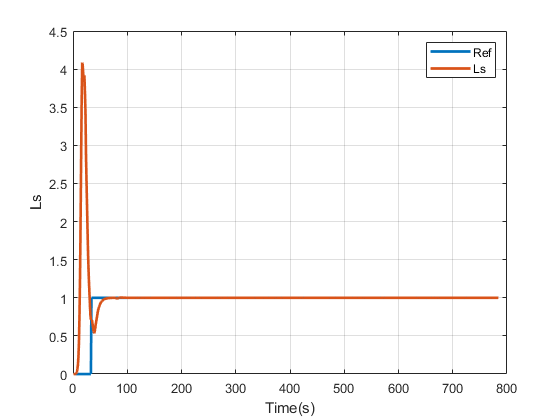

figure;
plot(out.Ls.signals.values(:,1),'LineWidth',2)
hold on
plot(out.Ls.signals.values(:,2),'LineWidth',2)
xlabel("Time(s)")
ylabel("Ls")
legend('Ref','Ls')
grid on

 Observa-se que o controlador CL consegue seguir as referências dadas sem sobressinal, e quando a perturbação F(s) atua ocorre um grande sobressinal de 400% fora dos requisitos

###  Controle de Ve(s):

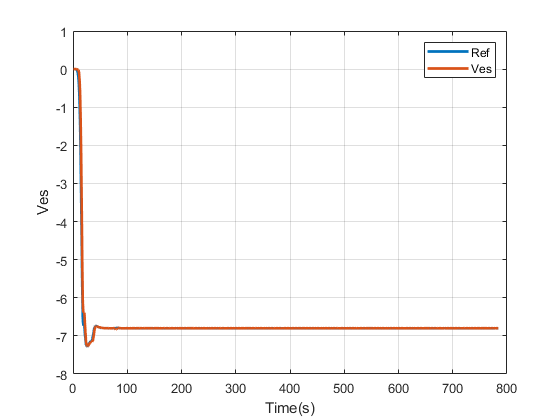

figure;
plot(out.Ves.signals.values(:,1),'LineWidth',2)
hold on
plot(out.Ves.signals.values(:,2),'LineWidth',2)
xlabel("Time(s)")
ylabel("Ves")
legend('Ref','Ves')
grid on

 Observa-se que o controlador CVe consegue seguir quase que perfeitamente a referência, que é sempre negativa;